% system
A = [0,1;0,0];
B1 = [-3,1,0;2,2,0];
B2 = [0;1];
C1 = [1,0];
D1 = [0,0,2];

% z(t)
C2 = [1,3;0,3;0,0];
D2 = [0;0;2];

% conditional test
C2'*D2 == 0

ans = 2×1 logical array
   1
   1


det(D2'*D2)

ans = 4

rank(ctrb(A,B2))

ans = 2

rank(obsv(A,C2))

ans = 2

B1*D1' == 0

ans = 2×1 logical array
   1
   1


det(D1*D1')

ans = 4

rank(obsv(A, C1))

ans = 2

rank(ctrb(A, B1))

ans = 2


% controller and observer
Q = icare(A,B2,C2'*C2,D2'*D2,0,eye(2),0)

Q =     1.6904    2.0000
    2.0000    9.3808


K = -inv(D2'*D2)*B2'*Q

K =    -0.5000   -2.3452


P = icare(A',C1',B1*B1',D1*D1',0,eye(2),0)

P =     9.2334    5.6569
    5.6569   17.0579


L = -P*C1'*inv(D1*D1')

L =    -2.3083
   -1.4142



% W(w->z)
syms s real;
W_wx = inv(eye(2)+inv(s*eye(2)-A)*B2*K*inv(s*eye(2)-A-B2*K-L*C1)*L*C1)*inv(s*eye(2)-A)*(B1-B2*K*inv(s*eye(2)-A-B2*K-L*C1)*L*D1);
W_wxhat = -inv(eye(2)+inv(s*eye(2)-A-B2*K-L*C1)*L*C1*inv(s*eye(2)-A)*B2*K)*inv(s*eye(2)-A-B2*K-L*C1)*(L*C1*inv(s*eye(2)-A)*B1+L*D1);
W_s = C2*W_wx+D2*K*W_wxhat;
[N11, D11] = numden(W_s(1,1));
[N12, D12] = numden(W_s(1,2));
[N13, D13] = numden(W_s(1,3));
[N21, D21] = numden(W_s(2,1));
[N22, D22] = numden(W_s(2,2));
[N23, D23] = numden(W_s(2,3));
[N31, D31] = numden(W_s(3,1));
[N32, D32] = numden(W_s(3,2));
[N33, D33] = numden(W_s(3,3));
WN11  = coeffs(N11, 'All');
WD11  = coeffs(D11, 'All');
WN12  = coeffs(N12, 'All');
WD12  = coeffs(D12, 'All');
WN13  = coeffs(N13, 'All');
WD13  = coeffs(D13, 'All');

WN21  = coeffs(N21, 'All');
WD21  = coeffs(D21, 'All');
WN22  = coeffs(N22, 'All');
WD22  = coeffs(D22, 'All');
WN23  = coeffs(N23, 'All');
WD23  = coeffs(D23, 'All');

WN31  = coeffs(N31, 'All');
WD31  = coeffs(D31, 'All');
WN32  = coeffs(N32, 'All');
WD32  = coeffs(D32, 'All');
WN33  = coeffs(N33, 'All');
WD33  = coeffs(D33, 'All');

W = [
    tf(double(WN11), double(WD11)), tf(double(WN12), double(WD12)), tf(double(WN13), double(WD13));
    tf(double(WN21), double(WD21)), tf(double(WN22), double(WD22)), tf(double(WN23), double(WD23));
    tf(double(WN31), double(WD31)), tf(double(WN32), double(WD32)), tf(double(WN33), double(WD33));
    ]

W =
 
  From input 1 to output...
              3.378e15 s^3 + 1.797e16 s^2 + 8.053e16 s + 2.367e16
   1:  -----------------------------------------------------------------
       1.126e15 s^4 + 5.239e15 s^3 + 8.25e15 s^2 + 5.034e15 s + 7.961e14
 
              6.755e15 s^3 + 3.144e16 s^2 + 9.48e16 s + 7.165e15
   2:  -----------------------------------------------------------------
       1.126e15 s^4 + 5.239e15 s^3 + 8.25e15 s^2 + 5.034e15 s + 7.961e14
 
                                                                             
             3.4e31 s^4 + 1.409e32 s^3 + 1.651e32 s^2 - 1.434e32 s - 2.627e31
                                                                             
   3:  -----------------------------------------------------------------------------
                                                                                    
       1.268e30 s^6 + 1.18e31 s^5 + 4.603e31 s^4 + 9.212e31 s^3 + 9.534e31 s^2      
                                                  

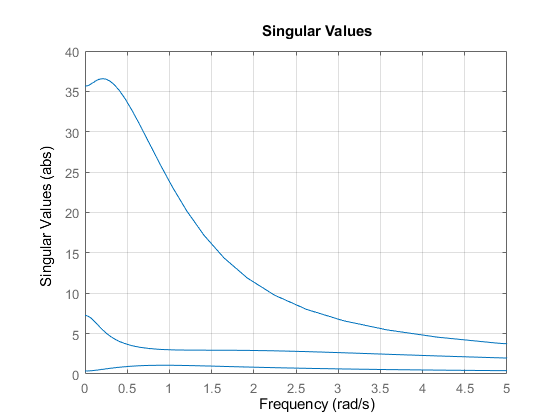

% W = [
%     tf(double(WN11), double(WD11)), tf(double(WN12), double(WD12)), tf(double(WN13), double(WD13));
%     tf(double(WN21), double(WD21)), tf(double(WN22), double(WD22)), tf(double(WN23), double(WD23));
%        ]
% ampW = bodeplot(W);
% setoptions(ampW,'FreqScale','linear','MagUnits','abs','Grid','on','PhaseVisible','off','IOGrouping','all');
% xlim([0 5]);

sinValW = sigmaplot(W);
setoptions(sinValW,'FreqScale','linear','MagUnits','abs','Grid','on');
xlim([0 5]);


% H_2 norm of transfer fuction
h_2 = norm(W)

h_2 = 22.6611


% H_inf norm of transfer fuction
h_inf = getPeakGain(W)

h_inf = 36.5719

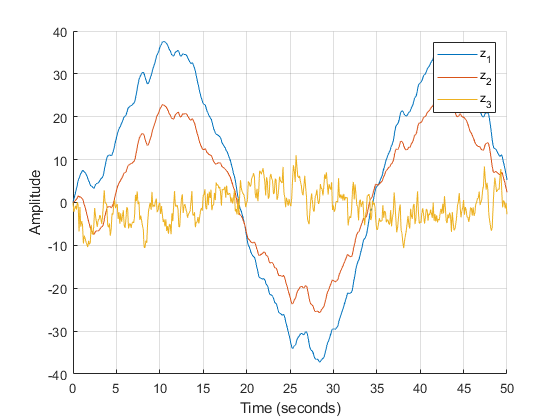

figure; %входные воздействия
grid on;
hold on;
plot(out.z.Time, out.z.Data(:,1))
plot(out.z.Time, out.z.Data(:,2))
plot(out.z.Time, out.z.Data(:,3))
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z_1", "z_2", "z_3")

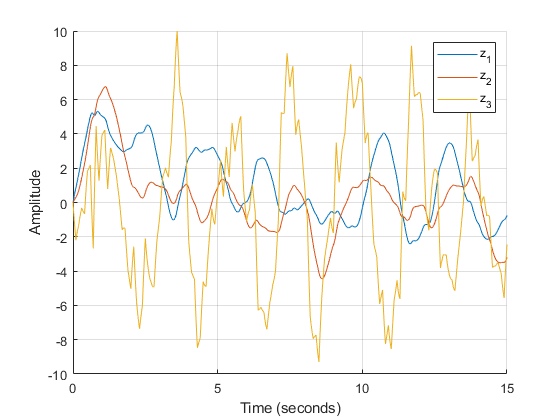

figure; %входные воздействия
grid on;
hold on;
plot(out.z1.Time, out.z1.Data(:,1))
plot(out.z1.Time, out.z1.Data(:,2))
plot(out.z1.Time, out.z1.Data(:,3))
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z_1", "z_2", "z_3")
xlim([0 15])